# COMP0118 Coursework 1: Parametric Models

## 1.1 Parameter Estimation and Mapping

**Load and Inspect Data**

I first load the data from the file `data.mat`.

%loading data into matlab
load('data_p1/data.mat');
dwis = double(dwis);
dwis=permute(dwis, [4, 1, 2, 3]);

I now display a single image slice to check that the image has been loaded correctly.

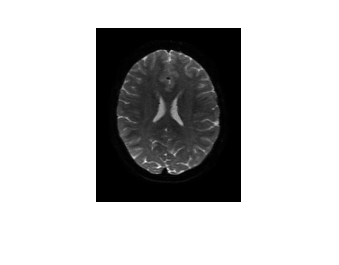

% middle slice of the 1st image volume, had b=0
imshow(flipud(squeeze(dwis(1, :, :, 72))'), []);

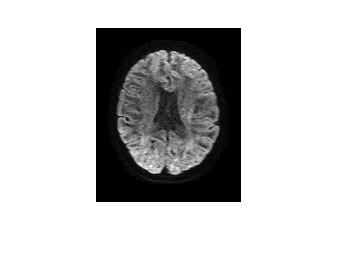

% Middle slice of the 2nd image volume, which has b=1000
imshow(flipud(squeeze(dwis(2,:,:,72))'), []);

Next, I load the gradient directions stored in the file bvecs.

qhat = load('data_p1/bvecs');
% and the bvalue array
bvals = 1000*sum(qhat.*qhat);

### **Core Questions**

#### **Q1.1.1 - Implementing linear diffusion tensor estimation and using it to map the mean diffusivity and fractional anisotropy over one slide of an image.**

Perform fitting for a single voxel

% Select a single voxel
Avox = dwis(:, 92, 65, 72);

% Create the design matrix
G = [ones(1, 108); -bvals.*qhat(1, :).^2; -2*bvals.*qhat(1,:).*qhat(2,:); -2*bvals.*qhat(1,:).*qhat(3,:); -bvals.*qhat(2,:).^2; -2*bvals.*qhat(2,:).*qhat(3,:); -bvals.*qhat(3,:).^2]';

% Compute parameter vector x
x = G\log(Avox);

Perform for all voxels

% Store diffusion tensor mapping here
dt_map72 = zeros(7, 145, 174);

% Precompute the design matrix
G = [ones(1, 108); -bvals.*qhat(1, :).^2; -2*bvals.*qhat(1,:).*qhat(2,:); -2*bvals.*qhat(1,:).*qhat(3,:); -bvals.*qhat(2,:).^2; -2*bvals.*qhat(2,:).*qhat(3,:); -bvals.*qhat(3,:).^2]';

% Repeat process for every voxel in slice
tic;
for i=1:145
    for j=1:174
        % Select voxel
        Avox = dwis(:, i, j, 72);
        
        if min(Avox) > 0
            % Compute x
            dt_map72(:, i, j) = G \ log(Avox);    
        end
    end
end
toc;

md_map72 = zeros(145, 174);
fa_map72 = zeros(145, 174);
cmap72 = zeros(145, 174, 3);

% Create the mean diffusivity map using dt_map72
for i=1:145
    for j=1:174
        
        % Select params for voxel
        x = dt_map72(:, i, j);
      
        % Get diffusion tensor
        D = [[x(2) x(3) x(4)]; [x(3) x(5) x(6)]; [x(4) x(6) x(7)]];
        
        % Compute eigenvectors and eigenvalues of D
        [V, L] = eig(D);
        Lbar = trace(L)/3;
        
        % Compute mean diffusivity
        md = (x(2, :) + x(5, :) + x(7, :)) / 3;
        md_map72(i, j) = md;
        
        % Compute fractional anisotropy map
        numerator = 0;
        denominator = 0;
        for k=1:3
            numerator = numerator + (L(k, k) - Lbar)^2;
            denominator = denominator + L(k, k)^2;
        end
        fa = sqrt((3/2) * numerator/denominator);
        fa_map72(i, j) = fa;
        
        % Find principal eigenvector
        [max_eigenval, idx] = max(diag(L));
        principal_e = V(:, idx);
        cmap72(i, j, :) = fa * abs(principal_e);
    end
end

% Visualize mean diffusion, fractional anisotropy and color maps
figure
imshow(flipud(md_map72'), [])
figure
imshow(flipud(fa_map72'), [])
figure
imshow(flipud(permute(cmap72, [2, 1, 3])), [])

#### **Q1.1.2 - Implement Ball-and-stick model to measure the density of axon fibres, indirectly, in each voxel.**

First, I implement the Ball and stick model for a single voxel.

% Select a single voxel
Avox = dwis(:,92,65,72);

% Define a starting point for the non-linear fit
startx_noisy = [3.5e+00 3e-03 2.5e-01 0 0];

% Define various options for the non-linear fitting
% algorithm.
h=optimset('MaxFunEvals',20000,...
 'Algorithm','quasi-newton',...
 'TolX',1e-10,...
 'TolFun',1e-10);

% Now run the fitting
[parameter_hat,RESNORM,~,~]=fminunc('BallStickSSD',startx_noisy,h,Avox,bvals,qhat);

format short e
parameter_hat
RESNORM

Now I implement the model on all voxels of the middle slice.

% Store fitted parameters for each voxel here
fitted_params_unconstrained_model = zeros(145, 174, 5);

tic;
for i=1:145
    for j=1:174
        % Select a single voxel
        Avox = dwis(:,i,j,72);

        if min(Avox) > 0
            % Define a starting point for the non-linear fit
            startx_noisy = [3.5e+00 3e-03 2.5e-01 0 0];
            
            % Define various options for the non-linear fitting
            % algorithm.
            h=optimset('MaxFunEvals',20000,...
             'Algorithm','quasi-newton',...
             'TolX',1e-10,...
             'TolFun',1e-10);
            
            % Now run the fitting
            [parameter_hat,RESNORM,~,~]=fminunc('BallStickSSD',startx_noisy,h,Avox,bvals,qhat);
         
            % Store parameter values in parameter_hat
            fitted_params_unconstrained_model(i, j, :) = parameter_hat;
        end
    end
end
toc;

Evaluating the results by comparing the MRI signal predicted using the fitted parameter model result with the true signal values.

% Select results for the middle voxel
Avox = dwis(:, 92, 65, 72);
[S, SSD] = BallStickEval(fitted_params_unconstrained_model(92, 65, :), Avox, bvals, qhat);

% Plotted predicted values vs true values
figure
set(gcf, 'Position', [10, 10, 900, 500])
plot(Avox, ' bs', 'MarkerSize', 16, 'LineWidth', 4);
hold on;
plot(S, ' rx', 'MarkerSize', 16, 'LineWidth', 4);
xlabel('q index');
ylabel('S');
legend('Data','Model');
xlim([0,110]);
title(sprintf('Comparison of Model predicted signal S (red) and true measurement in Avox (blue) \nSSD = %.2f', SSD))

#### **Q1.1.3 - Adapt the implementation from 1.1.2 using the transformation method with **`fminunc`** to allow for only realistic settings of parameters.**

Implement on a single voxel

% Select a single voxel
Avox = dwis(:,92,65,72);

% Define a starting point for the non-linear fit
startx_noisy = [sqrt(3.5e+00) sqrt(3e-03) sqrt(-log(2.5e-01)) 0 0];

% Define various options for the non-linear fitting
% algorithm.
h=optimset('MaxFunEvals',20000,...
 'Algorithm','quasi-newton',...
 'TolX',1e-10,...
 'TolFun',1e-10);

% Now run the fitting
[parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('BallStickSSD_transformation',startx_noisy,h,Avox,bvals,qhat);

% Transform parameters back to original values
parameter_hat(:, 1) = parameter_hat(:, 1)^2;
parameter_hat(:, 2) = parameter_hat(:, 2)^2;
parameter_hat(:, 3) = exp(-1 * parameter_hat(:, 3)^2);

format short e
parameter_hat
RESNORM

Implement for all voxels

% Store fitted params for transformation model here
fitted_params_transformation_model = zeros(145, 174, 5);

tic;
for i=1:145
    for j=1:174
        % Select a single voxel
        Avox = dwis(:,i,j,72);
        
        if min(Avox) > 0
            % Define a starting point for the non-linear fit
            startx_noisy = [sqrt(3.5e+00) sqrt(3e-03) sqrt(-log(2.5e-01)) 0 0];
            
            % Define various options for the non-linear fitting
            % algorithm.
            h=optimset('MaxFunEvals',20000,...
             'Algorithm','quasi-newton',...
             'TolX',1e-10,...
             'TolFun',1e-10);
            
            % Now run the fitting
            [parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('BallStickSSD_transformation',startx_noisy,h,Avox,bvals,qhat);
         
            % Transform parameters back to original values
            parameter_hat(:, 1) = parameter_hat(:, 1)^2;
            parameter_hat(:, 2) = parameter_hat(:, 2)^2;
            parameter_hat(:, 3) = exp(-1 * parameter_hat(:, 3)^2);
            
            % Store parameter values in parameter_hat
            fitted_params_transformation_model(i, j, :) = parameter_hat;
        end
    end
end
toc;

Evaluating the results by comparing the MRI signal predicted using the fitted parameter model result with the true signal values.

% Select results for the middle voxel
Avox = dwis(:, 92, 65, 72);
[S, SSD] = BallStickEval(fitted_params_transformation_model(92, 65, :), Avox, bvals, qhat);

% Plotted predicted values vs true values
figure
set(gcf, 'Position', [10, 10, 900, 500])
plot(Avox, ' bs', 'MarkerSize', 16, 'LineWidth', 4);
hold on;
plot(S, ' rx', 'MarkerSize', 16, 'LineWidth', 4);
xlabel('q index');
ylabel('S');
legend('Data','Model');
xlim([0,110]);
title(sprintf('Comparison of Model predicted signal S (red) and true measurement in Avox (blue) \nSSD = %.2f', SSD))

#### **Q1.1.4 - Perform experiments now with many different starting points to assess if we really have converged to global minimum.**

n_runs = 100;
% Store errors per run here
errors_per_run = zeros(1, n_runs);

% Select a single voxel
i = 100;
j = 80;
Avox = dwis(:,i,j,72);

% Visualize where it is in the brain
figure
imshow(flipud(squeeze(dwis(1, :, :, 72))'), []);
axis on;
hold on;
plot(92, 65, 'r+', 'MarkerSize', 10, 'LineWidth', 2);
plot(72, 95, 'g+', 'MarkerSize', 10, 'LineWidth', 2);
plot(52, 88, 'b+', 'MarkerSize', 10, 'LineWidth', 2);
plot(100, 110, 'c+', 'MarkerSize', 10, 'LineWidth', 2);
plot(60, 50, 'm+', 'MarkerSize', 10, 'LineWidth', 2);
plot(72, 47, 'y+', 'MarkerSize', 10, 'LineWidth', 2);
plot(60, 120, 'w+', 'MarkerSize', 10, 'LineWidth', 2);
% plot(100, 80, 'w+', 'MarkerSize', 10, 'LineWidth', 2);

n = 1;
while n <= n_runs

    % Define a starting point for the non-linear fit
    startx = [3.5e+00 3e-03 2.5e-01 0 0];
    
    % Add gaussian noise to each of parameters
    startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
    startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    while any(startx_noisy(:, 1:2) < 0)
        startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
        startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    end
    startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    while startx_noisy(:, 3) > 1 || startx_noisy(:, 3) < 0
        startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    end
    startx_noisy(:, 4) = startx(:, 4) + 1e-01*randn;
    startx_noisy(:, 5) = startx(:, 5) + 1e-01*randn;
    
    % Perform inverse transformation on first three parameters
    startx_noisy(:, 1:2) = sqrt(startx_noisy(:, 1:2));
    startx_noisy(:, 3) = sqrt(-log(startx_noisy(:, 3)));
    
    % Define various options for the non-linear fitting
    % algorithm.
    h=optimset('MaxFunEvals',20000,...
     'Algorithm','quasi-newton',...
     'TolX',1e-10,...
     'TolFun',1e-10, 'Display', 'off');
    
    % Now run the fitting
    try
        [parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('BallStickSSD_transformation',startx_noisy,h,Avox,bvals,qhat); 
    catch
        continue;
    end
    
    % Perform transformation back on parameters
    parameter_hat(:, 1) = parameter_hat(:, 1)^2;
    parameter_hat(:, 2) = parameter_hat(:, 2)^2;
    parameter_hat(:, 3) = exp(-parameter_hat(:, 3)^2);
    
    % Store
    errors_per_run(:, n) = RESNORM;
    
    n = n + 1;
end

Plot the errors per run

figure
plot(n_runs)
hold on;
plot(errors_per_run)
xlabel('Iterations')
ylabel('Error')
title('Errors on every iteration')

% Find proportion of trials with smallest value of RESNORM
min_error = min(errors_per_run)
count = 0;
tolerance = 0.1;
for n=1:n_runs
    if (errors_per_run(n) - min_error <= tolerance)
        count = count + 1;
    end
end

proportion = count / n_runs

% proportion = p(the run will find a global min) = p
% p(atleast 1 global min in n runs) = 1 - p(no global min in N runs)
% 0.95 = 1 - nC0*p^0*(1-p)^n
n_runs = log(0.05)/log(1-proportion)

#### Q1.1.5 - Create parameter maps over image slice for S0, d, f and RESNORM. Also Create a fibre direction map.

% Select 72nd image slice
image = dwis(:, :, :, 72);

% Compute feature maps for this slice
parameter_maps = createParameterMaps(image, bvals, qhat, 10);

% Select parameter maps
S0_map72 = parameter_maps(:, :, 1);
d_map72 = parameter_maps(:, :, 2);
f_map72 = parameter_maps(:, :, 3);
theta_map72 = parameter_maps(:, :, 4);
phi_map72 = parameter_maps(:, :, 5);
RESNORM_map72 = parameter_maps(:, :, 6);

% Visualize the feature maps
figure
imshow(flipud(S0_map72'), [])

figure
imshow(flipud(d_map72'), [])

figure
imshow(flipud(f_map72'), [])

figure
imshow(flipud(RESNORM_map72'), [])

% compute fibre direction map
figure
set(gcf, 'Position', [10, 10, 450, 500])
fibredir_map72 = zeros(145, 174, 2);
for i=1:145
    for j=1:174
        fibredir_map72(i, j, :) = f_map72(i, j) .* [cos(theta_map72(i, j))*sin(theta_map72(i, j)) sin(phi_map72(i, j))*sin(theta_map72(i, j))];
    end
end
quiver(flipud(fibredir_map72(:, :, 1)'), flipud(fibredir_map72(:, :, 2)'))

## 1.2 Confidence and Uncertainty

### **Core Questions:**

#### **Q1.2.1 - Using parametric bootstrap to estimate 2-sigma range and 95% range for S0, d and f in ball-and-stick model.**

% Select a voxel 
Avox = dwis(:, 70, 90, 72); floor()
format short e
% Generate bootstrap samples
bootstrap_samples = PBootstrap(Avox, bvals, qhat, 10, 1000);

Plot histograms of each parameter

bootstrap_samples_sorted = sort(bootstrap_samples, 2, 'ascend');

figure;
histogram(bootstrap_samples(1, :));
xlabel('S0');
ylabel('Frequency');
title('Posterior for S0');
hold on;

two_sigma_range_S0_high = mean(bootstrap_samples(1,:)) + 2*std(bootstrap_samples(1,:))
two_sigma_range_S0_low = mean(bootstrap_samples(1,:)) - 2*std(bootstrap_samples(1,:))

ninety_five_percent_range_S0_high = bootstrap_samples_sorted(1, ceil(length(bootstrap_samples)*(1-0.025)))
ninety_five_percent_range_S0_low = bootstrap_samples_sorted(1, ceil(length(bootstrap_samples)*0.025))

figure;
histogram(bootstrap_samples(2, :));
xlabel('d');
ylabel('Frequency');
title('Posterior for d');

two_sigma_range_d_high = mean(bootstrap_samples(2,:)) + 2*std(bootstrap_samples(2,:))
two_sigma_range_d_low = mean(bootstrap_samples(2,:)) - 2*std(bootstrap_samples(2,:))

ninety_five_percent_range_d_high = bootstrap_samples_sorted(2, ceil(length(bootstrap_samples)*(1-0.025)))
ninety_five_percent_range_d_low = bootstrap_samples_sorted(2, ceil(length(bootstrap_samples)*0.025))

figure;
histogram(bootstrap_samples(3, :));
xlabel('f');
ylabel('Frequency');
title('Posterior for f');

two_sigma_range_f_high = mean(bootstrap_samples(3,:)) + 2*std(bootstrap_samples(3,:))
two_sigma_range_f_low = mean(bootstrap_samples(3,:)) - 2*std(bootstrap_samples(3,:))

ninety_five_percent_range_f_high = bootstrap_samples_sorted(3, ceil(length(bootstrap_samples)*(1-0.025)))
ninety_five_percent_range_f_low = bootstrap_samples_sorted(3, ceil(length(bootstrap_samples)*0.025))

#### **Q1.2.2 - Using Markov Chain Monte-Carlo (MCMC) to provide another estimate of 2-sigma range and 95% range for paramters.**

% Select a voxel
Avox = dwis(:, 92, 65, 72);

rng(1)
% Generate bootstrap samples - 50 and 700
mcmc_samples = MCMC(Avox, bvals, qhat, 40, 450, 5000);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


Plot parameter values over iterations

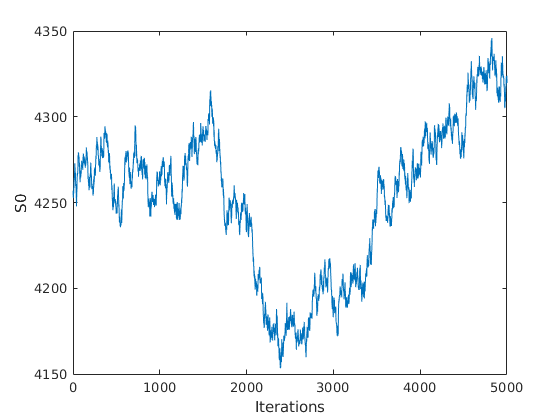

figure
plot(mcmc_samples(:, 1))
% ylim([4100, 4500])
xlabel('Iterations')
ylabel('S0')

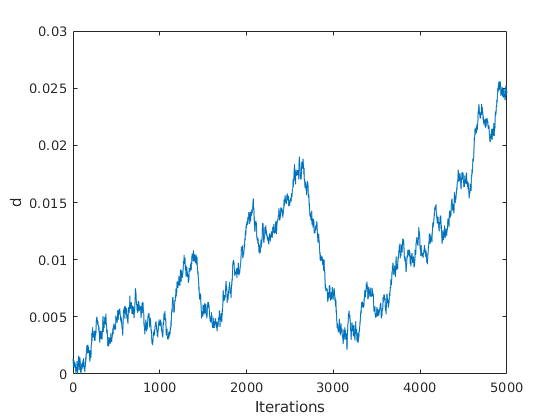


figure
plot(mcmc_samples(:, 2))
% ylim([0.3, 0.42])
xlabel('Iterations')
ylabel('d')

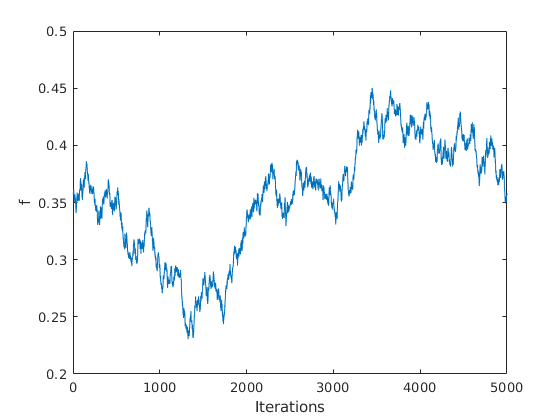


figure
plot(mcmc_samples(:, 3))
% ylim([1e-03, 1.3e-03])
xlabel('Iterations')
ylabel('f')

Plot histograms of parameter samples

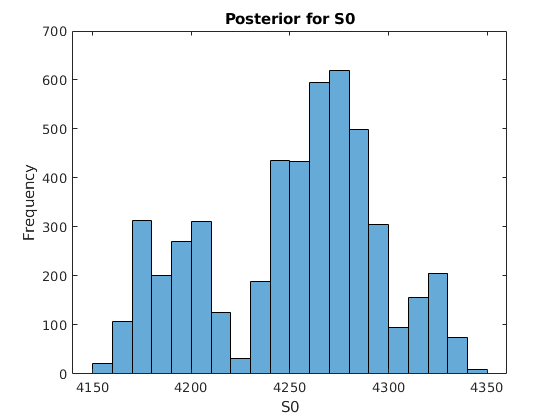

mcmc_samples_sorted = sort(mcmc_samples, 1, 'ascend');

figure
histogram(mcmc_samples(:, 1))
xlabel('S0');
ylabel('Frequency');
title('Posterior for S0');


two_sigma_range_S0_high = mean(mcmc_samples(:, 1)) + 2*std(mcmc_samples(:, 1))

two_sigma_range_S0_high = 4.3399e+03

two_sigma_range_S0_low = mean(mcmc_samples(:, 1)) - 2*std(mcmc_samples(:, 1))

two_sigma_range_S0_low = 4.1638e+03


ninety_five_percent_range_S0_high = mcmc_samples_sorted(ceil(length(mcmc_samples)*(1-0.025)), 1)

ninety_five_percent_range_S0_high = 4.3277e+03

ninety_five_percent_range_S0_low = mcmc_samples_sorted(ceil(length(mcmc_samples)*0.025), 1)

ninety_five_percent_range_S0_low = 4.1698e+03

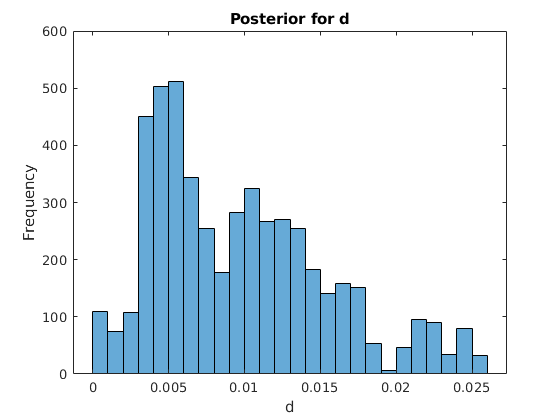


figure
histogram(mcmc_samples(:, 2))
xlabel('d');
ylabel('Frequency');
title('Posterior for d');


two_sigma_range_S0_high = mean(mcmc_samples(:, 2)) + 2*std(mcmc_samples(:, 2))

two_sigma_range_S0_high = 0.0213

two_sigma_range_S0_low = mean(mcmc_samples(:, 2)) - 2*std(mcmc_samples(:, 2))

two_sigma_range_S0_low = -0.0019


ninety_five_percent_range_S0_high = mcmc_samples_sorted(ceil(length(mcmc_samples)*(1-0.025)), 2)

ninety_five_percent_range_S0_high = 0.0235

ninety_five_percent_range_S0_low = mcmc_samples_sorted(ceil(length(mcmc_samples)*0.025), 2)

ninety_five_percent_range_S0_low = 0.0011

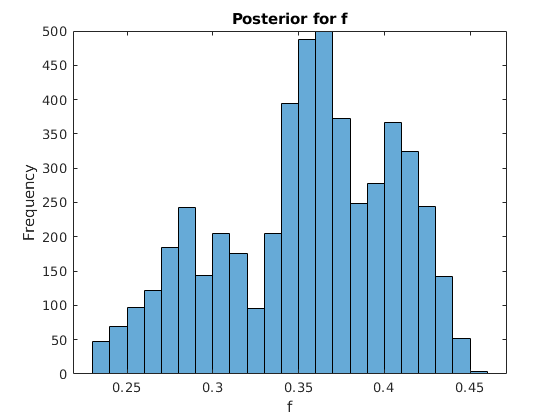


figure
histogram(mcmc_samples(:, 3))
xlabel('f');
ylabel('Frequency');
title('Posterior for f');


two_sigma_range_S0_high = mean(mcmc_samples(:, 3)) + 2*std(mcmc_samples(:, 3))

two_sigma_range_S0_high = 0.4563

two_sigma_range_S0_low = mean(mcmc_samples(:, 3)) - 2*std(mcmc_samples(:, 3))

two_sigma_range_S0_low = 0.2536


ninety_five_percent_range_S0_high = mcmc_samples_sorted(ceil(length(mcmc_samples)*(1-0.025)), 3)

ninety_five_percent_range_S0_high = 0.4340

ninety_five_percent_range_S0_low = mcmc_samples_sorted(ceil(length(mcmc_samples)*0.025), 3)

ninety_five_percent_range_S0_low = 0.2508

## 1.3 Model Selection

### Loading Data

% Load the diffusion signal
fid = fopen('data_p1.3-1.4/isbi2015_data_normalised.txt', 'r', 'b');
fgetl(fid); % Read in the header
D = fscanf(fid, '%f', [6, inf])'; % Read in the data
fclose(fid);

% Select the first of the 6 voxels
meas = D(:,1);

% Load the protocol
fid = fopen('data_p1.3-1.4/isbi2015_protocol.txt', 'r', 'b');
fgetl(fid);
A = fscanf(fid, '%f', [7, inf]);
fclose(fid);

% Create the protocol
grad_dirs = A(1:3,:);
G = A(4,:);
delta = A(5,:);
smalldel = A(6,:);
TE = A(7,:);

GAMMA = 2.675987E8;
bvals = ((GAMMA*smalldel.*G).^2).*(delta-smalldel/3);
% convert bvals units from s/m^2 to s/mm^2
bvals = bvals/10^6;

### Core Questions: 

#### Q1.3.1 - Fit Ball-&-Stick model from 1.1.3 to the new data.

n_runs = 100;
% Store errors per run here
errors_per_run = zeros(1, n_runs);
min_error = 1e+10;

n = 1;
while n <= n_runs
    % Select a single voxel
    Avox = D(:,1);

    % Define a starting point for the non-linear fit
    startx = [3.5e+00 3e-03 2.5e-01 0 0];
    
    % Add gaussian noise to each of parameters
    startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
    startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    % Repeat if the noisy start value isnt within the constraints
    while any(startx_noisy(:, 1:2) < 0)
        startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
        startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    end
    startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    % Repeat if the noisy start value isnt within the constraints
    while startx_noisy(:, 3) > 1 || startx_noisy(:, 3) < 0
        startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    end
    startx_noisy(:, 4) = startx(:, 4) + 1e-01*randn;
    startx_noisy(:, 5) = startx(:, 5) + 1e-01*randn;
    
    % Perform inverse transform
    startx_noisy(:, 1:2) = sqrt(startx_noisy(:, 1:2));
    startx_noisy(:, 3) = sqrt(-log(startx_noisy(:, 3)));
    
    % Define various options for the non-linear fitting
    % algorithm.
    h=optimset('MaxFunEvals',20000,...
     'Algorithm','quasi-newton',...
     'TolX',1e-10,...
     'TolFun',1e-10, 'Display', 'off');
    
    % Now run the fitting
    try
        [parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('BallStickSSD_transformation',startx_noisy,h,Avox,bvals,grad_dirs); 
    catch
        continue
    end
    
    % Store
    errors_per_run(:, n) = RESNORM;
    
    % Save parameters if they have the smallest minimum
    if RESNORM < min_error
        min_error = RESNORM;
        best_params_BS = parameter_hat;
    end
    
    n = n + 1;
end

figure
plot(n_runs)
hold on;
plot(errors_per_run)
xlabel('Iterations')
ylabel('Error')
title('Errors on every iteration')

% Find proportion of trials with smallest value of RESNORM
min_error
count = 0;
tolerance = 0.1;
for n=1:n_runs
    if (errors_per_run(n) - min_error <= tolerance)
        count = count + 1;
    end
end

best_params_BS

proportion = count / n_runs

% proportion = p(the run will find a global min) = p
% p(atleast 1 global min in n runs) = 1 - p(no global min in N runs)
% 0.95 = 1 - nC0*p^0*(1-p)^n
n_runs = log(0.05)/log(1-proportion)

#### Q1.3.2 - Adapt code further to fit various different models.

Implement Diffusion Tensor Model

% Select a single voxel
Avox = D(:, 1);

% Create the design matrix
G = [ones(1, length(Avox)); -bvals.*grad_dirs(1, :).^2; -2*bvals.*grad_dirs(1,:).*grad_dirs(2,:); -2*bvals.*grad_dirs(1,:).*grad_dirs(3,:); -bvals.*grad_dirs(2,:).^2; -2*bvals.*grad_dirs(2,:).*grad_dirs(3,:); -bvals.*grad_dirs(3,:).^2]';

% Compute parameter vector x
x = G\log(Avox);

% Compute error 
S = G*x; 
error = sum((Avox - S).^2)

Implement zeppelin-and-stick model

n_runs = 10;
% Store errors per run here
errors_per_run = zeros(1, n_runs);
min_error = 1e+10;

n = 1;
while n <= n_runs
    % Select a single voxel
    Avox = D(:,1);

    % Define a starting point for the non-linear fit
    startx = [3.5e+00 3e-03 2.5e-01 3e-03 0 0];
    
    % Add gaussian noise to each of parameters
    startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
    startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    startx_noisy(:, 4) = startx(:, 4) + randn;
    % Repeat if the noisy start value isnt within the constraints
    while any(startx_noisy(:, [1:2, 4]) < 0)
        startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
        startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
        startx_noisy(:, 4) = startx(:, 4) + randn;
    end
    startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    % Repeat if the noisy start value isnt within the constraints
    while startx_noisy(:, 3) > 1 || startx_noisy(:, 3) < 0
        startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    end
    startx_noisy(:, 5) = startx(:, 5) + 1e-01*randn;
    startx_noisy(:, 6) = startx(:, 6) + 1e-01*randn;
    
    % Perform inverse transformation on first three parameters
    startx_noisy(:, [1:2]) = sqrt(startx_noisy(:, [1:2]));
    startx_noisy(:, 3) = sqrt(-log(startx_noisy(:, 3)));
    startx_noisy(:, 4) = sqrt(startx_noisy(:, 4)/2);
    
    % Define various options for the non-linear fitting
    % algorithm.
    h=optimset('MaxFunEvals',20000,...
     'Algorithm','quasi-newton',...
     'TolX',1e-10,...
     'TolFun',1e-10, 'Display', 'off');
    
    % Now run the fitting
    [parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('ZeppelinStickSSD',startx_noisy,h,Avox,bvals,grad_dirs);
    
%     parameter_hat(:, 1) = parameter_hat(:, 1)^2;
%     parameter_hat(:, 2) = parameter_hat(:, 2)^2;
%     parameter_hat(:, 3) = exp(-parameter_hat(:, 3)^2);
%     parameter_hat(:, 4) = 2*parameter_hat(:, 4)^2;
   
    % Store
    errors_per_run(:, n) = RESNORM;
    
    % Save parameters if they have the smallest minimum
    if RESNORM < min_error
        min_error = RESNORM;
        best_params_ZS = parameter_hat;
    end
    
    n = n + 1;
end

best_params_ZS

% Find proportion of trials with smallest value of RESNORM
min_error
count = 0;
tolerance = 0.1;
for n=1:n_runs
    if (errors_per_run(n) - min_error <= tolerance)
        count = count + 1;
    end
end

proportion = count / n_runs

% proportion = p(the run will find a global min) = p
% p(atleast 1 global min in n runs) = 1 - p(no global min in N runs)
% 0.95 = 1 - nC0*p^0*(1-p)^n
n_runs = log(0.05)/log(1-proportion)

Implement zeppelin-and-stick with tortuousity

n_runs = 100;
% Store errors per run here
errors_per_run = zeros(1, n_runs);
min_error = 1e+10;

n = 1;
while n <= n_runs
    % Select a single voxel
    Avox = D(:,1);

    % Define a starting point for the non-linear fit
    startx = [3.5e+00 3e-03 2.5e-01 0 0];
    
    % Add gaussian noise to each of parameters
    startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
    startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    % Repeat if the noisy start value isnt within the constraints
    while any(startx_noisy(:, 1:2) < 0)
        startx_noisy(:, 1) = startx(:, 1) + 1e+03*randn;
        startx_noisy(:, 2) = startx(:, 2) + 1e-03*randn;
    end
    startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    % Repeat if the noisy start value isnt within the constraints
    while startx_noisy(:, 3) > 1 || startx_noisy(:, 3) < 0
        startx_noisy(:, 3) = startx(:, 3) + 1e-01*randn;
    end
    startx_noisy(:, 4) = startx(:, 4) + 1e-01*randn;
    startx_noisy(:, 5) = startx(:, 5) + 1e-01*randn;
    
    % Perform inverse transformation on first three parameters
    startx_noisy(:, 1:2) = sqrt(startx_noisy(:, 1:2));
    startx_noisy(:, 3) = sqrt(-log(startx_noisy(:, 3)));
    
    % Define various options for the non-linear fitting
    % algorithm.
    h=optimset('MaxFunEvals',20000,...
     'Algorithm','quasi-newton',...
     'TolX',1e-10,...
     'TolFun',1e-10, 'Display', 'off');
    
    % Now run the fitting
    try
        [parameter_hat,RESNORM,EXITFLAG,OUTPUT]=fminunc('ZeppelinStickTortuositySSD',startx_noisy,h,Avox,bvals,grad_dirs); 
    catch
        continue
    end
    
%     parameter_hat(:, 1) = parameter_hat(:, 1)^2;
%     parameter_hat(:, 2) = parameter_hat(:, 2)^2;
%     parameter_hat(:, 3) = exp(-parameter_hat(:, 3)^2);
   
    % Store
    errors_per_run(:, n) = RESNORM;
    
    % Save parameters if they have the smallest minimum
    if RESNORM < min_error
        min_error = RESNORM;
        best_params_ZST = parameter_hat;
    end
    
    n = n + 1;
end

best_params_ZST

% Find proportion of trials with smallest value of RESNORM
min_error
count = 0;
tolerance = 0.1;
for n=1:n_runs
    if (errors_per_run(n) - min_error <= tolerance)
        count = count + 1;
    end
end

proportion = count / n_runs

% proportion = p(the run will find a global min) = p
% p(atleast 1 global min in n runs) = 1 - p(no global min in N runs)
% 0.95 = 1 - nC0*p^0*(1-p)^n
n_runs = log(0.05)/log(1-proportion)

#### Q1.3.3 - Compute AIC and BIC for the 3 models.

% Store number of parameters in each model
N_BS = 5;
N_ZS = 6;
N_ZST = 5;

% store number of values in voxel
K = length(Avox);

% compute SSD for each model
SSD_BS = BallStickSSD_transformation(best_params_BS, Avox, bvals, grad_dirs);
SSD_ZS = ZeppelinStickSSD(best_params_ZS, Avox, bvals, grad_dirs);
SSD_ZST = ZeppelinStickTortuositySSD(best_params_ZST, Avox, bvals, grad_dirs);

% compute sigma^2 for each model
sigma_BS = (1/K)*SSD_BS;
sigma_ZS = (1/K)*SSD_ZS;
sigma_ZST = (1/K)*SSD_ZST;

% compute logL for each model
logL_BS = (-K/2)*(log(2*pi) + log(sigma_BS) + 1);
logL_ZS = (-K/2)*(log(2*pi) + log(sigma_ZS) + 1);
logL_ZST = (-K/2)*(log(2*pi) + log(sigma_ZST) + 1);

% Compute AIC score
AIC_BS = 2*(N_BS+1) + K*log((1/K)*SSD_BS)
AIC_ZS = 2*(N_ZS+1) + K*log((1/K)*SSD_ZS)
AIC_ZST = 2*(N_ZST+1) + K*log((1/K)*SSD_ZST)

% Compute BIC score
BIC_BS = N_BS*log(K) - 2*logL_BS
BIC_ZS = N_ZS*log(K) - 2*logL_ZS
BIC_ZST = N_ZST*log(K) - 2*logL_ZST